clear; clc; close all;

split_percent = 0.8;
split_idx = split_percent * size(labels, 2);
X_Train = features(:, :, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, :, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [121×1×34560 double]
      Labels: [121×34560 double]


dsTest =   MyDataStore with properties:

    Features: [121×1×8640 double]
      Labels: [121×8640 double]


layers = [
    imageInputLayer([Q, 1], "Normalization", "none");
    convolution2dLayer([21, 1], 24, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([15, 1], 20, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([11, 1], 12, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([5, 1], 5, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([3, 1], 1, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    flattenLayer()
    regressionLayer()
]

layers =   18×1 Layer array with layers:

     1   ''   Image Input           121×1×1 images
     2   ''   2-D Convolution       48 21×1 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization   Batch normalization
     4   ''   ReLU                  ReLU
     5   ''   2-D Convolution       40 15×1 convolutions with stride [1  1] and padding 'same'
     6   ''   Batch Normalization   Batch normalization
     7   ''   ReLU                  ReLU
     8   ''   2-D Convolution       24 11×1 convolutions with stride [1  1] and padding 'same'
     9   ''   Batch Normalization   Batch normalization
    10   ''   ReLU                  ReLU
    11   ''   2-D Convolution       10 5×1 convolutions with stride [1  1] and padding 'same'
    12   ''   Batch Normalization   Batch normalization
    13   ''   ReLU                  ReLU
    14   ''   2-D Convolution       1 3×1 convolutions with str

layers = [
    imageInputLayer([Q, 1], "Normalization", "none");
    convolution2dLayer([48, 1], 24, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([40, 1], 20, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([32, 1], 16, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([16, 1], 8, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([8, 1], 4, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([3, 1], 1, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    flattenLayer()
    regressionLayer()
]

layers =   21×1 Layer array with layers:

     1   ''   Image Input           121×1×1 images
     2   ''   2-D Convolution       24 48×1 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization   Batch normalization
     4   ''   ReLU                  ReLU
     5   ''   2-D Convolution       20 40×1 convolutions with stride [1  1] and padding 'same'
     6   ''   Batch Normalization   Batch normalization
     7   ''   ReLU                  ReLU
     8   ''   2-D Convolution       16 32×1 convolutions with stride [1  1] and padding 'same'
     9   ''   Batch Normalization   Batch normalization
    10   ''   ReLU                  ReLU
    11   ''   2-D Convolution       8 16×1 convolutions with stride [1  1] and padding 'same'
    12   ''   Batch Normalization   Batch normalization
    13   ''   ReLU                  ReLU
    14   ''   2-D Convolution       4 8×1 convolutions with str

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvi

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         9.06 |         41.0 |          0.0010 |
|       1 |          50 |       00:00:05 |         2.23 |          2.5 |          0.0010 |
|       1 |         100 |       00:00:08 |         1.63 |          1.3 |          0.0010 |
|       1 |         150 |       00:00:11 |         1.34 |          0.9 |          0.0010 |
|       1 |         200 |       00:00:16 |         1.26 |          0.8 |          0.0010 |
|       1 |         250 |       00:00:19 |         1.21 |          0.7 |          0.0010 |
|       2 |         300 |       00:00:23 |         1.20 |         

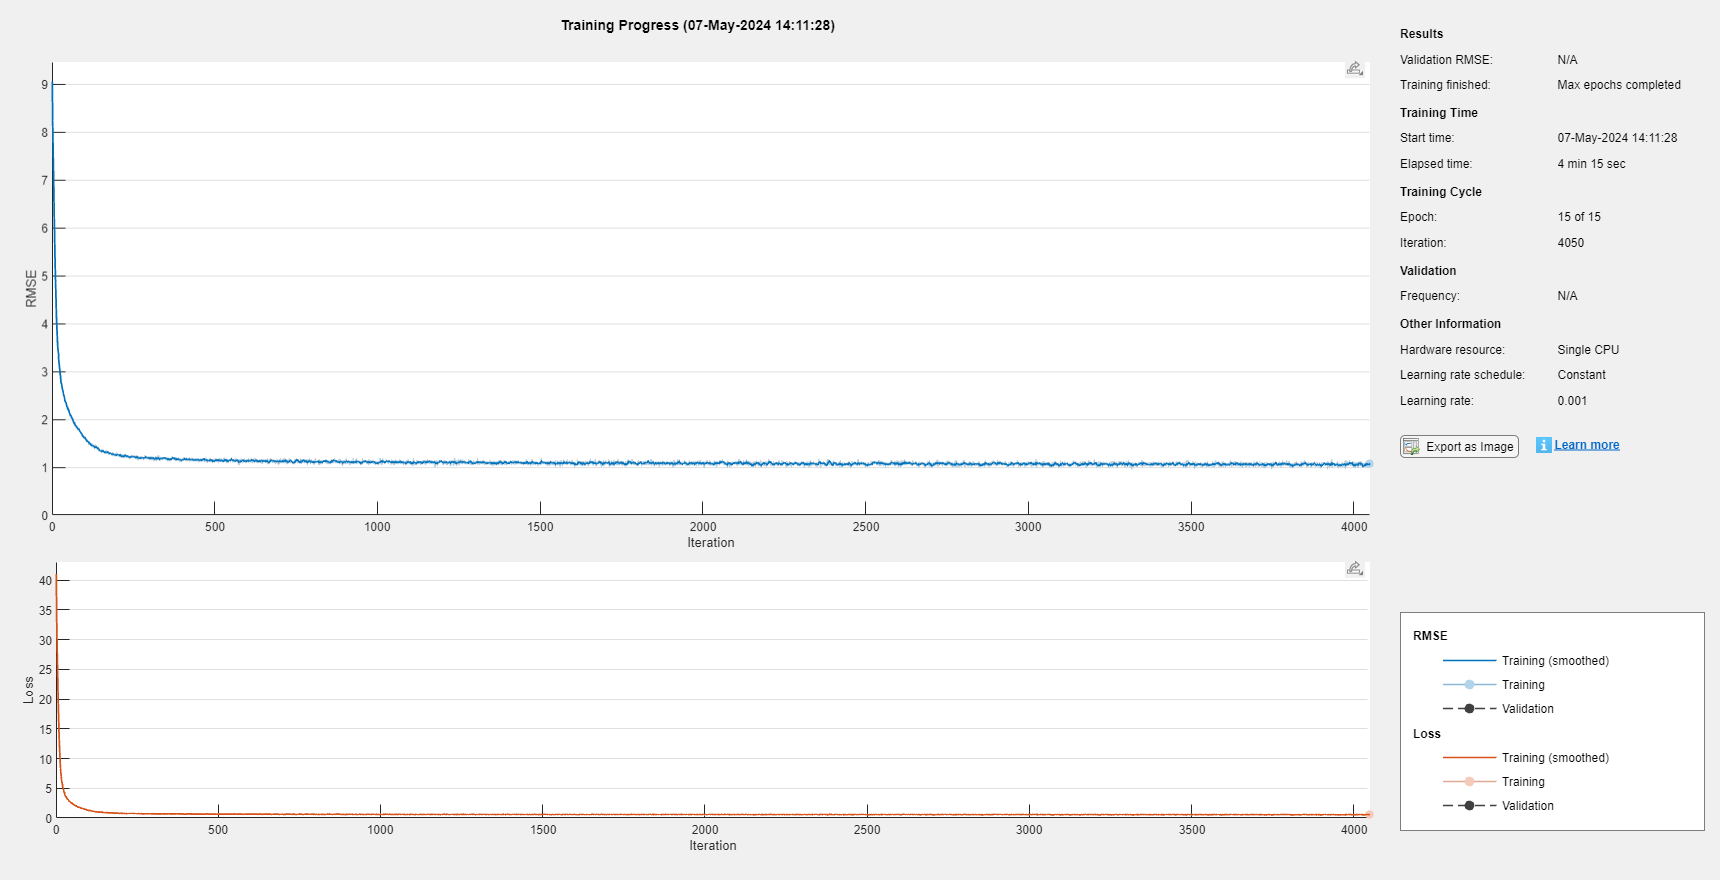

net =   SeriesNetwork with properties:

         Layers: [21×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |         8.03 |         32.2 |          0.0010 |
|       1 |          50 |       00:00:09 |         2.17 |          2.3 |          0.0010 |
|       1 |         100 |       00:00:11 |         1.67 |          1.4 |          0.0010 |
|       1 |         150 |       00:00:13 |         1.41 |          1.0 |          0.0010 |
|       1 |         200 |       00:00:16 |         1.32 |          0.9 |          0.0010 |
|       1 |         250 |       00:00:18 |         1.25 |          0.8 |          0.0010 |
|       2 |         300 |       00:00:21 |         1.20 |         

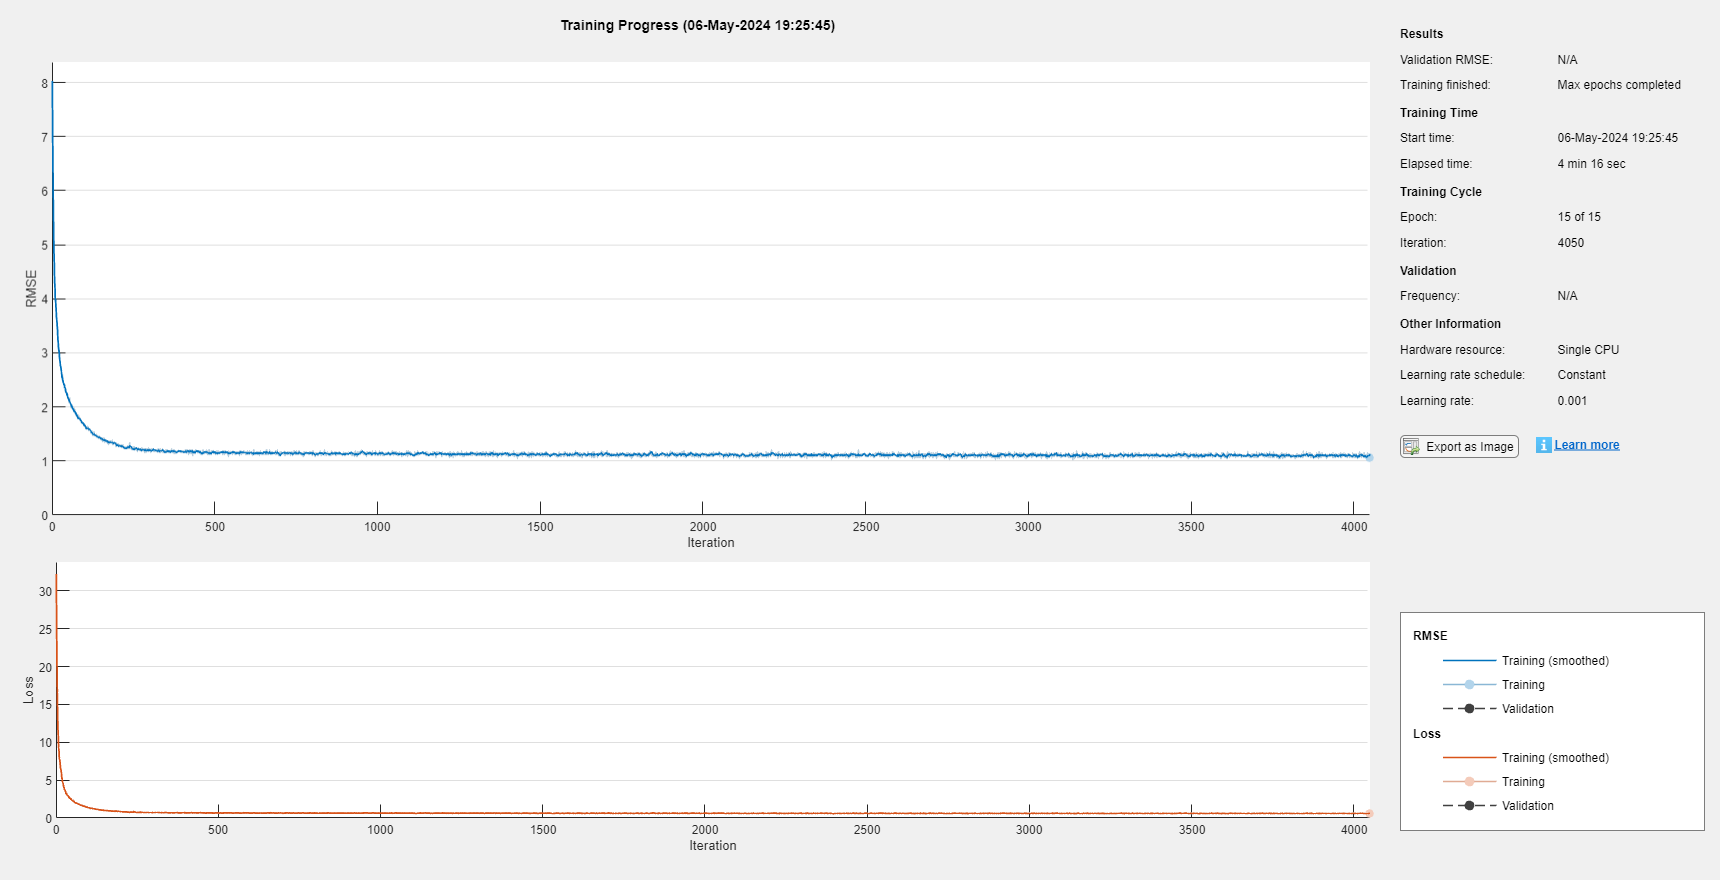

net =   SeriesNetwork with properties:

         Layers: [18×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

YPred = predict(net, X_Test).';
E = size(X_Test, 2);
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

# Testing

load Sparse_1D_CNN_v2.mat
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

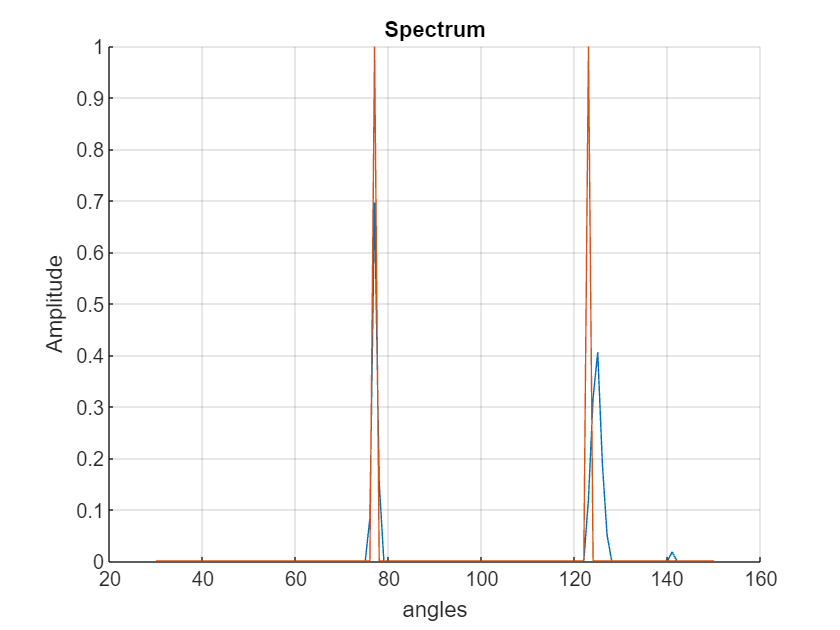

actual doa angles = 77.2672 123.0085


Test(DOA, net);

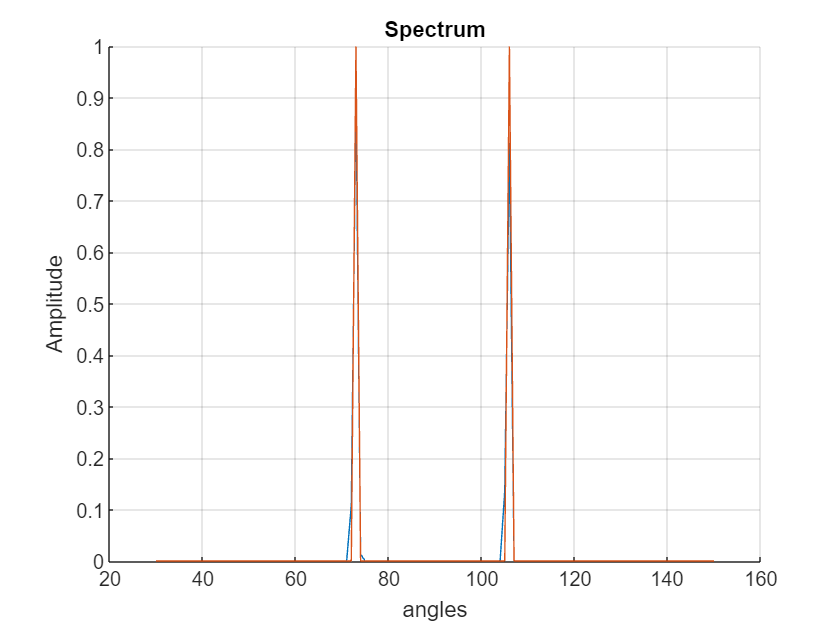

actual doa angles = 72.775 105.7113


Test(DOA, net);

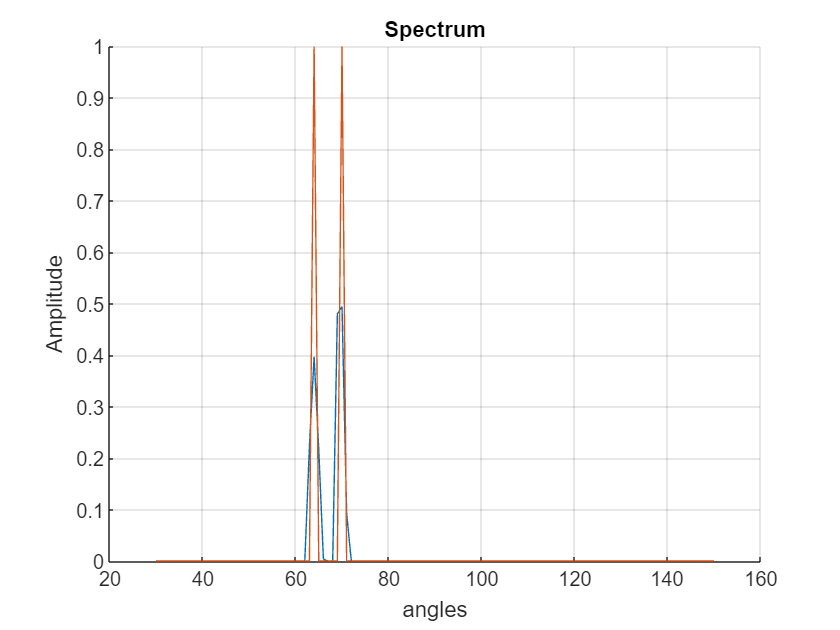

actual doa angles = 63.5813 70.119


Test(DOA, net);

function Test(DOA, net)
sensor_locations = [1 2 5 8 10] - 1; % SLA with 5 sensors
M = length(sensor_locations);
N = sensor_locations(M) + 1;

K = 2;
L = 70;
delta_phi = 1;
phi_min = 30;
phi_max = 150;

angles = phi_min:delta_phi:phi_max;
Q = length(angles);

label = zeros(Q, 1);

A_sparse = DOA.Array_Manifold(0.5, sensor_locations, angles);

doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);
rounded_doa = round(doa);
inds = (rounded_doa - phi_min) / delta_phi + 1;
label(inds) = 1;

% original case
A = DOA.Array_Manifold(0.5, sensor_locations, doa);
L = 70; % # of snapshots
s = DOA.Source_Generate(K, L);
SNR_dB = -5 + sign(randi(3) - 2.5) * 5 + rand * 10;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;
R = (1 / L) * (y * y');

z = R(:);
A1 = DOA.khatri_rao(conj(A_sparse), A_sparse);

feature = abs(A1' * z);
feature = (feature - mean(feature)) / var(feature);

pred = predict(net, feature);

figure; hold on;
plot(angles, pred);
plot(angles, label);
title('Spectrum');
ylabel('Amplitude');
xlabel('angles');
grid on;

msg = "actual doa angles =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);
end